# Driving Pattern Basic Component

Copyright 2021 The MathWorks, Inc.

## Open the Model

mdl = "DrivingPatternBasic_test_harness";
if not(bdIsLoaded(mdl))
  % This automatically runs setup script within callback function.
  open_system(mdl)
else
  % Run setup script
  DrivingPatternBasic_setup
end

## Load Inputs

Input signals are defined as timetable object in a separate MATLAB function. This script only loads it for visualization and simulation.

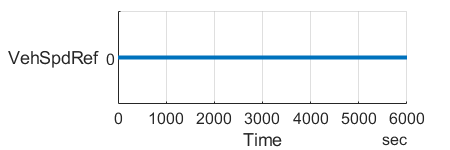

fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, t_end] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig, "InputPattern","standstill_charge" );

summary(inputSignals_DrivingPattern.VehSpdRef)

RowTimes:

    Time: 2×1 duration
        Values:
            Min           0 sec    
            Median        3000 sec 
            Max           6000 sec 
            TimeStep      6000 sec 

Variables:

    VehSpdRef: 2×1 double

        Properties:
            Units:  km/hr
            Continuity:  continuous
        Values:

            Min          0    
            Median       0    
            Max          0    



## Run Simulation

% Set initial conditions

% Override parameters
drivingPattern.useFromWorkspace_tf = true;

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);
